# Submission: Multiband ADMM-based compressed sensing demo (One slot, No adaptive learning parameters)

## 1. Initialization

Assumptions:

- Time-invariant channel (Hchan)

- Frequency-**dependent** RCS (channel gains)

- Noise variance constant across all frequencies

clc
clear all;
close all;
rng(57);

currentScriptPath = mfilename('fullpath');
currentFolder = fileparts(currentScriptPath);
addpath(currentFolder)

% Constants
c = physconst('lightspeed');
colors = [043 048 122;
          119 194 243;
          247 238 246;
          216 160 199;
          169 111 176]/255;           % Colors for visualization

% System Parameters
MB_f = [12 18 22]*1e9;          % Subband frequencies
Q = 1000;                       % Number of subcarriers
MB_fb = [120 180 220] * 1e3;    % Subcarrier spacing
MB_d = (c./MB_f)./2;            % Antenna spacing
M = 60;                         % Number of antennas
K = length(MB_f);               % Number of subbands
modulation = 4;                 % 4-QAM
PT = 30;                         % Transmit power (dBm)
N0 = -174;                      % Thermal noise power spectral density (dBm)
NF = 7;                         % Noise figure (dB)

% Path parameters
npaths = 12;
gains = rand(npaths,K) + 1i * rand(npaths,K);           % DEPENDENT on subband frequency
delays = round((40 + rand(npaths,1) * 160)) * 1e-9;     % ON-GRID delays between 40 and 200 ns (limit to farfield)
angles = round(rand(npaths,1) * 180 - 90);              % ON-GRID angles between -90 and 90 deg
% npaths = 3;
% gains = ones(npaths,K);
% delays = [150 100 50].' * 1e-9;
% angles = [-45 0 45].';
PL = 1./(4*pi*MB_f.*delays).^2;                         % Pathloss

% ADMM Parameters
max_iter = 1000;                    % Max ADMM iterations
rho = 1;                            % ADMM penalty parameter (1)
alpha = 1;                          % Step size scaling (1)
tol_abs = 1e-8;                     % Absolute tolerance
tol_rel = 1e-8;                     % Relative tolerance
anglegrid = (-90:1:90).';        % Angle grid
delaygrid = (0:1:200).'*1e-9;    % Delay grid
L_angle = length(anglegrid);
L_delay = length(delaygrid);

Note:

- delay resolution ~ 1/bandwidth

- angle resolution (HPBW) ~ 180*lambda/(pi*d*(M-1))

If d > lambda/2, you have **grating lobes effect, limiting the steerable range.** Also, system bandwidth should be greater than channel coherence bandwidth so that **system delay resolution is smaller than channel delay spread to resolve the delays.**

BW = Q.*MB_fb;
disp(['Bandwidth: [',num2str(BW/1e6),'] MHz']);    % Display bandwidth

Bandwidth: [120  180  220] MHz


## 2. Channel and Signal Generation 

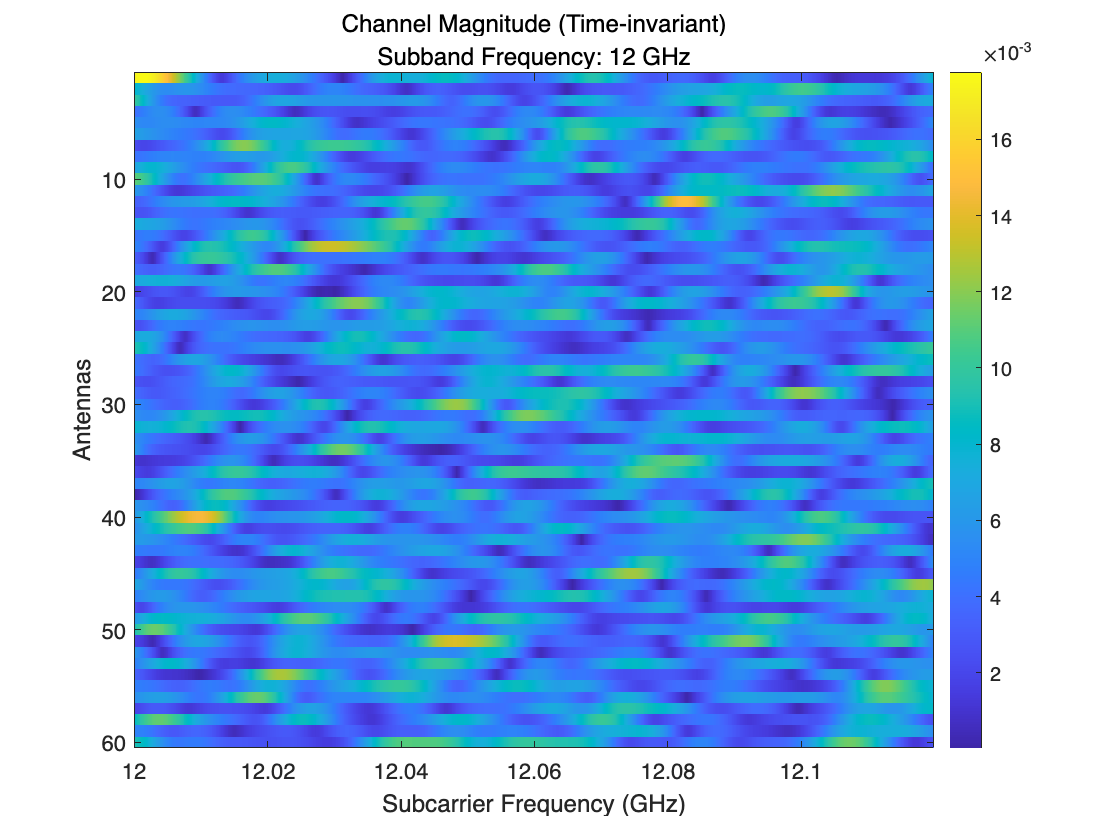

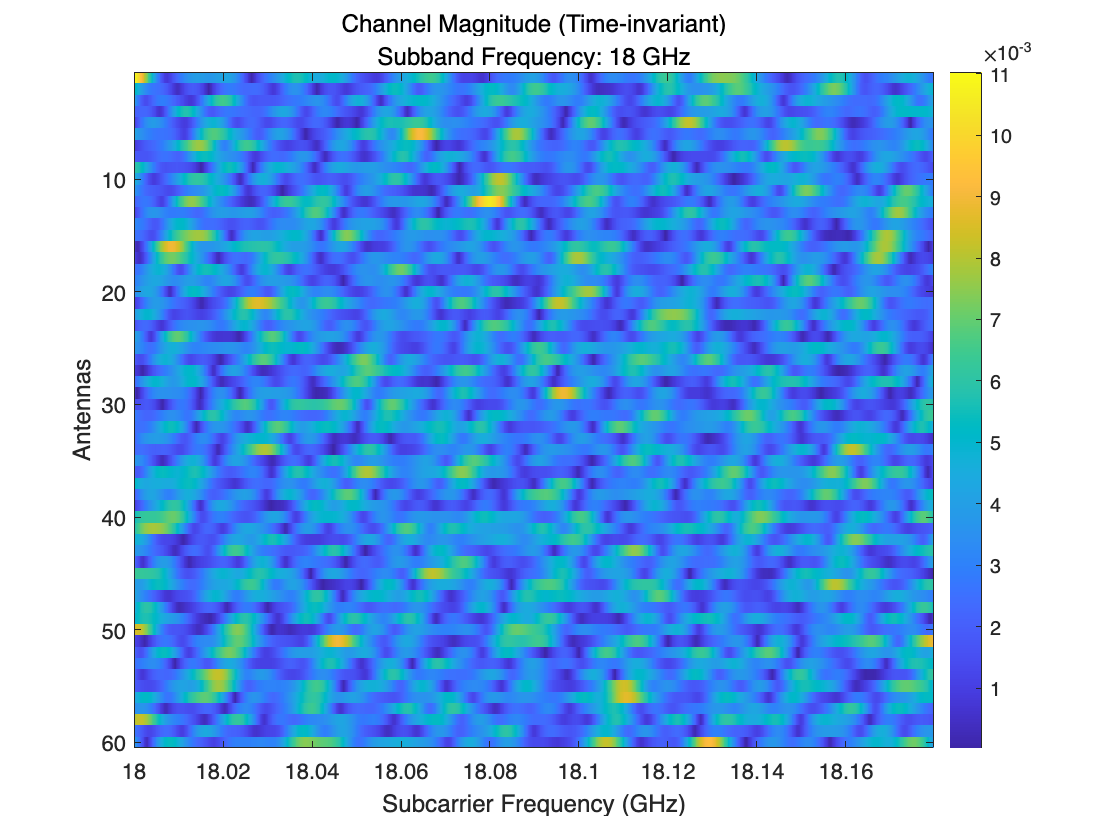

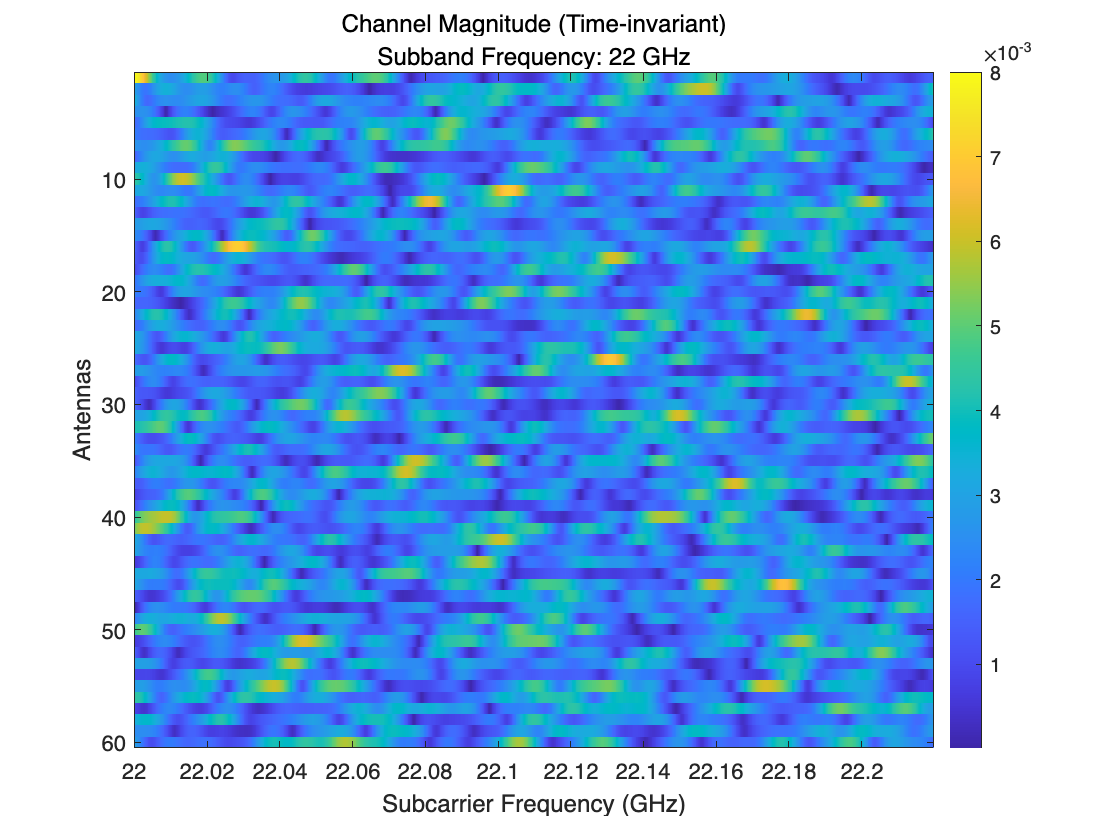

% Initialize Variables
s = cell(K,1);                              % Pilot symbols
Y = cell(K,1);                              % Received signal
snr = zeros(K,1);                           % SNR of Received signal
A1 = cell(K,1);                             % Delay Dictionary
A2 = cell(K,1);                             % Angle Dictionary
norm_A_full = zeros(K,1);                   % Matrix L2-norm used in calculating step size

% Noiser Variance
noisevar_total = db2pow(N0+NF) * sum(BW);   % Total noise variance (mW)
noisevar = db2pow(N0+NF) * BW;              % Noise variance per subband (mW)

for k = 1:K
    fb = MB_fb(k);
    d = MB_d(k);
    f = MB_f(k);

    % Channel Matrix (Hchan)
    Hchan = zeros(M,Q);
    for p = 1:npaths
        a_R = exp(-1i*2*pi*d*f*(0:M-1).'*sind(angles(p))/c); % Rx steering
        a_F = exp(-1i*2*pi*(f+fb*(0:Q-1).')*delays(p)); % Freq steering
        Hchan = Hchan + sqrt(db2pow(PT))*sqrt(PL(p,k)).*gains(p,k).* (a_R*a_F.'); % Outer product
    end

    % Visualization of Channel
    figure
    freqaxis = (f+fb*(0:(Q-1)))/1e9;
    imagesc(freqaxis,1:M,abs(Hchan));
    xlabel('Subcarrier Frequency (GHz)');
    ylabel('Antennas');
    colorbar;
    title('Channel Magnitude (Time-invariant)', ...
        ['Subband Frequency: ',num2str(MB_f(k)/1e9),' GHz']);

    % Pilot symbols (s)
    s{k} = qammod(randi([0,modulation-1],Q,1),modulation,'UnitAveragePower',true);

    % Received signal (Y)
    W = sqrt(noisevar(k)/2) * (randn(M,Q) + 1i * randn(M,Q));
    Y{k} = Hchan.*s{k}.' + W;

    % Delay Dictionary (A1)
    A1{k} = zeros(Q, L_delay);
    for i = 1:L_delay
        A1{k}(:,i) = s{k} .* exp(-1i*2*pi*(f+fb*(0:Q-1).')*delaygrid(i));
    end

    % Angle Dictionary (A2)
    A2{k} = zeros(M, L_angle);
    for i = 1:L_angle
        A2{k}(:,i) = exp(-1i*2*pi*d*(0:M-1).'*f*sind(anglegrid(i))/c);
    end

    norm_A2 = norm(A2{k}, 2);
    norm_A1 = norm(A1{k}, 2);
    norm_A_full(k) = norm_A1 * norm_A2;
end

We can see that the channel is quite **frequency-selective (has a much smaller coherence bandwidth) within our system bandwidth** for all subbands!

% Calculate and Display SNR
for k = 1:K
    snr(k) = pow2db(mean(abs(Y{k}).^2,'all') / noisevar(k));
    disp([num2str(MB_f(k)/1e9),' GHz', ...
        ' - SNR: ',num2str(snr(k)),' dB']);
end

12 GHz - SNR: 41.3895 dB
18 GHz - SNR: 35.8477 dB
22 GHz - SNR: 32.2448 dB


We can see that with increasing pathloss at higher subband frequencies, the effective SNR decreases. 

## 3. Benchmark: Beamforming Approach 

P = zeros(L_angle,L_delay);
for k = 1:K
    fb = MB_fb(k);
    d = MB_d(k);
    f = MB_f(k);
    for theta_idx = 1:length(anglegrid)
        theta = anglegrid(theta_idx);
        a_theta = exp(-1i*2*pi*d*f*(0:M-1).'*sind(theta)/c);
        for tau_idx = 1:length(delaygrid)
            tau = delaygrid(tau_idx);
            a_tau = exp(-1i*2*pi*(f+fb*(0:Q-1).')*tau);
            P(theta_idx,tau_idx) = P(theta_idx,tau_idx) + (1/K) * abs((s{k}.*a_tau).'*Y{k}'*a_theta);
        end
    end
end
P_norm = P/max(P,[],'all'); % Normalization

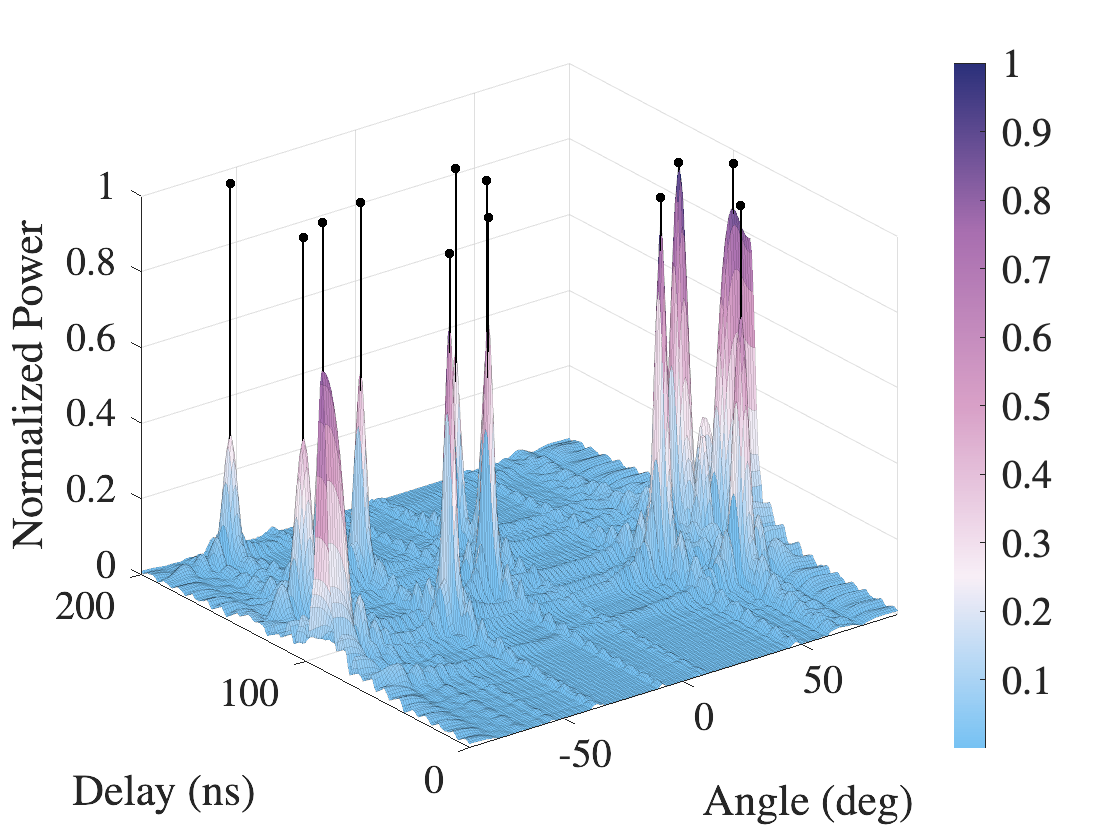

figure
[gridy,gridx] = meshgrid(delaygrid * 1e9,anglegrid);
surf(gridx,gridy,P_norm,'EdgeAlpha',0.125); hold on;
colormap(matColorMap(colors([2,3,4,5,1],:),8192)); colorbar;
for idx = 1:npaths
    plot3([angles(idx) angles(idx)],[delays(idx) delays(idx)] * 1e9,[0 1],'.-k','LineWidth',1,'MarkerSize',15)
end
hold off;
xlabel('Angle (deg)','Interpreter','latex'); xlim([-90 90]);
ylabel('Delay (ns)','Interpreter','latex'); ylim([0 200]);
zlabel('Normalized Power','Interpreter','latex');
formatMyFigure();

## 4. Compressed Sensing ADMM Solver

epsilon_total = 1.2*sqrt(M*Q*noisevar_total).';     % Constraint bound initialization (ideal)
epsilon = epsilon_total.*sqrt(BW./sum(BW));

For epsilon initialization, I used the actual noise variance as this demo does not consider adaptive epsilon

% Initialize variables
HH = zeros(L_delay*L_angle, K); % Matrix to optimize
Z = cell(K,1);                 % Auxiliary variables
U = cell(K,1);                 % Dual variables
gamma = alpha / (rho * max(norm_A_full.^2,[],'all')); % Step size
reslog = []; % Diagonostic: residual convergence
for k = 1:K
    Z{k} = zeros(M,Q);    % Initialize Z_k
    U{k} = zeros(M,Q);    % Initialize U_k
end

% ADMM iterations
for iter = 1:max_iter

    % For checking convergence
    Z_prev = Z;
    primal_res = 0;
    dual_res = 0;

    % Update HH using proximal gradient
    G = zeros(size(HH));
    for k = 1:K
        % Compute A_full,k * h_k using Kronecker product
        h_k = HH(:,k);
        h_k_mat = reshape(h_k, [L_angle, L_delay]);
        AhA = A2{k} * h_k_mat * A1{k}.';
        % Gradient computation
        res_mat = AhA - (Z{k} - U{k});
        grad_mat = A2{k}' * res_mat * conj(A1{k}); %A1 conj'ed already in dictionary (via modulation)
        G(:,k) = rho * grad_mat(:);
    end
    HH_temp = HH - gamma * G;

    % Apply proximal operator (group soft-thresholding)
    rownorms = vecnorm(HH_temp,2,2);
    HH = max(0,1 - gamma./rownorms) .* HH_temp;

    for k = 1:K
        % Compute A_full,k * h_k
        h_k = HH(:,k);
        h_k_mat = reshape(h_k, L_angle, L_delay);
        AhA = A2{k} * h_k_mat * A1{k}.';

        % Update z_k by projection
        % Project onto ||Y_k - Z_k||_F <= epsilon_k
        C_k = AhA + U{k};
        diff = C_k - Y{k};
        norm_diff = norm(diff,'fro');
        if norm_diff <= epsilon(k)
            Z{k} = C_k;
        else
            Z{k} = Y{k} + (epsilon(k)/norm_diff) * diff;
        end

        % Update dual variables
        U{k} = U{k} + (AhA - Z{k});

        % Primal and dual residuals
        if norm(AhA - Z{k},'fro') > primal_res
            primal_res = norm(AhA - Z{k},'fro');
        end
        if rho * norm(Z{k} - Z_prev{k}, 'fro') > dual_res
            dual_res = rho * norm(Z{k} - Z_prev{k}, 'fro');
        end
    end

    % Display progress
    if mod(iter,50) == 0
        disp(['Iteration ',num2str(iter)]);
    end

    % Add termination criteria based on residuals
    % Primal tolerance
    max_norm_Z = max(cellfun(@(Z) norm(Z,'fro'), Z));
    max_norm_AhA = max(cellfun(@(A1,A2,h) norm(A2*reshape(h, [L_angle,L_delay])*A1.','fro'), ...
        A1, A2, num2cell(HH,1).'));
    tol_primal = tol_abs * sqrt(numel(Z{1})) + tol_rel * max(max_norm_AhA, max_norm_Z);

    % Dual tolerance
    max_norm_U = max(cellfun(@(U) norm(rho * U,'fro'), U)); % Max ||rho U_k||_F
    tol_dual = tol_abs * sqrt(numel(Z{1})) + tol_rel * max_norm_U;

    % Diagonostic: Residual convergence
    reslog(iter,:) = [primal_res, tol_primal, dual_res, tol_dual];

    % --- Check termination ---
    if primal_res < tol_primal && dual_res < tol_dual
        disp(['Converged at iteration ',num2str(iter)]);
        break;
    end

end

Iteration 50
Iteration 100
Iteration 150
Iteration 200
Iteration 250
Iteration 300
Iteration 350
Iteration 400
Iteration 450
Iteration 500
Iteration 550
Iteration 600
Iteration 650
Iteration 700
Iteration 750
Iteration 800
Iteration 850
Iteration 900
Iteration 950
Iteration 1000


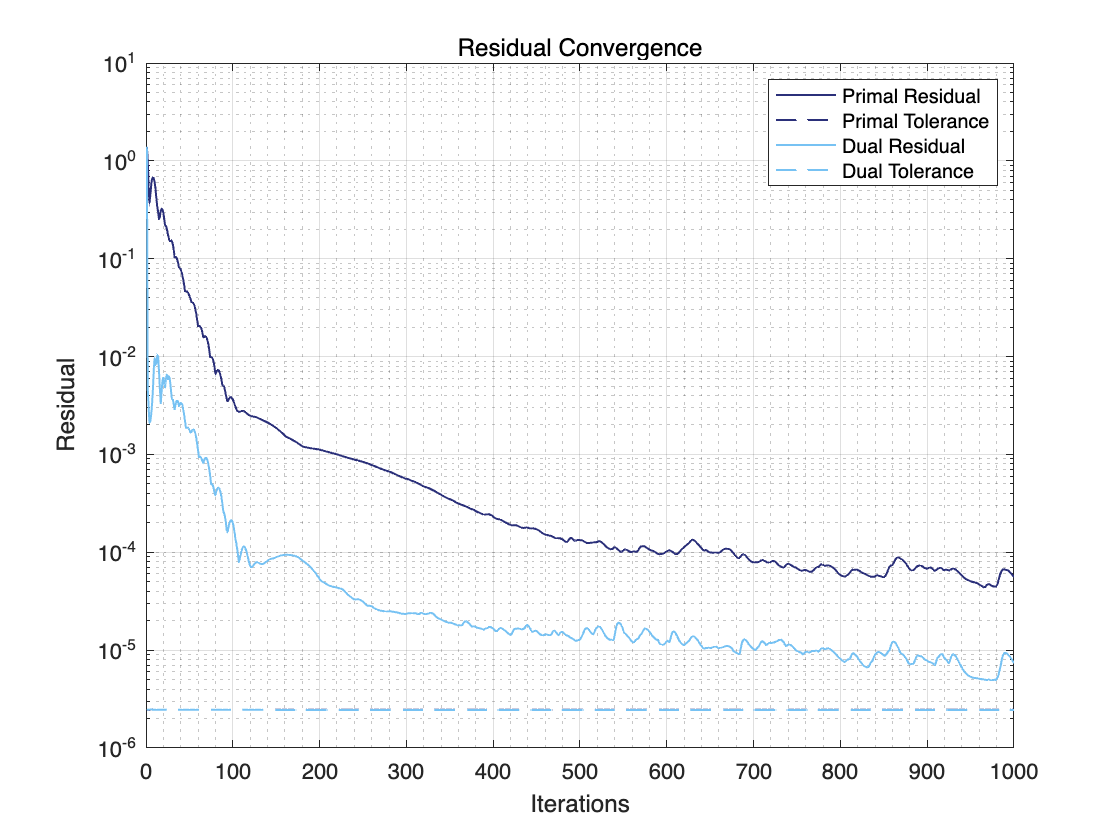

Hestmag = reshape(mean(abs(HH),2),[L_angle, L_delay]); % k averaging

% Diagonostic: Residual convergence
figure
semilogy(reslog(:,1),'Color',colors(1,:),'LineWidth',1); hold on;
semilogy(reslog(:,2),'--','Color',colors(1,:),'LineWidth',1)
semilogy(reslog(:,3),'Color',colors(2,:),'LineWidth',1);
semilogy(reslog(:,4),'--','Color',colors(2,:),'LineWidth',1); hold off;
xlabel('Iterations');
ylabel('Residual');
xlim([0 iter]);
title('Residual Convergence')
legend('Primal Residual','Primal Tolerance','Dual Residual','Dual Tolerance');
grid on;
grid minor;

Hestmag_norm = Hestmag / max(Hestmag,[],'all');

## 5. Visualization of Sensing Output

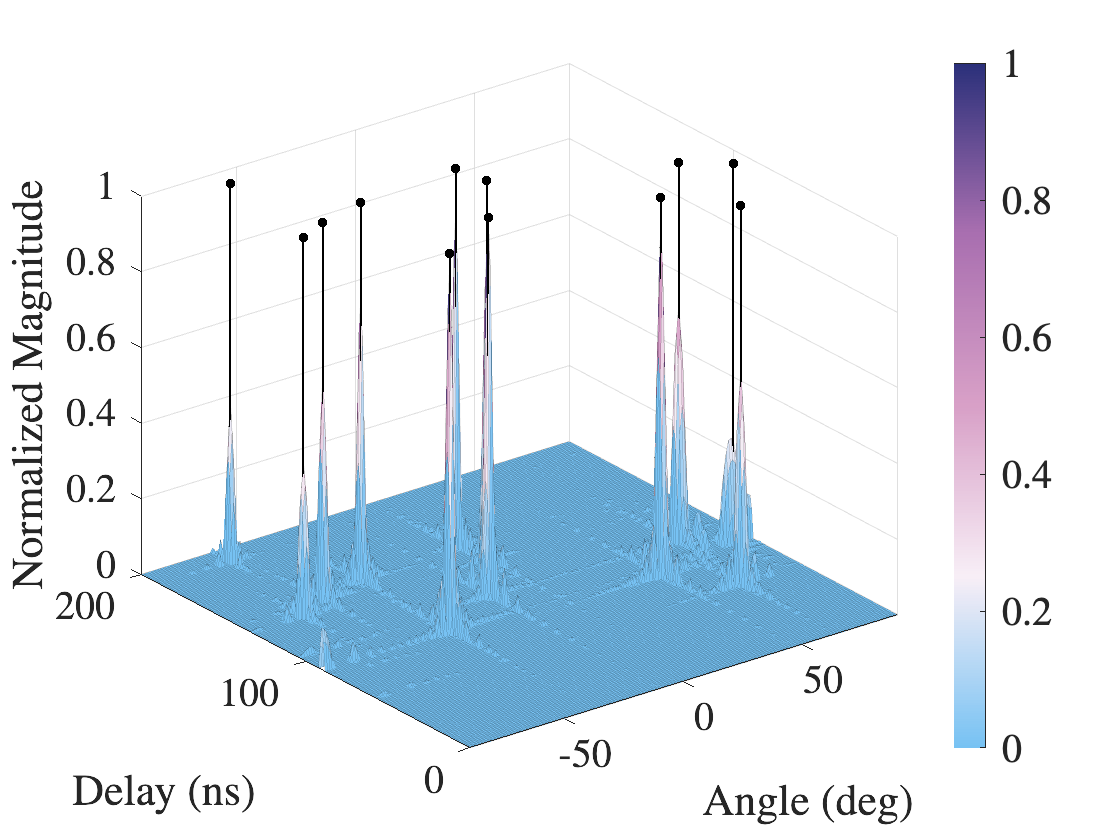

figure
[gridy,gridx] = meshgrid(delaygrid * 1e9,anglegrid);
surf(gridx,gridy,Hestmag_norm,'EdgeAlpha',0.125); hold on;
colormap(matColorMap(colors([2,3,4,5,1],:),8192)); colorbar;
for idx = 1:npaths
    plot3([angles(idx) angles(idx)],[delays(idx) delays(idx)]*1e9,[0 1],'.-k','LineWidth',1,'MarkerSize',15)
end
hold off;
xlabel('Angle (deg)','Interpreter','latex'); xlim([-90 90]);
ylabel('Delay (ns)','Interpreter','latex'); ylim([0 200]);
zlabel('Normalized Magnitude','Interpreter','latex');
formatMyFigure();

## 6. Peakfinding

This function is used: Kristupas Tikuišis (2025). [peaks2 - find peaks in 2D data without additional toolbox](https://www.mathworks.com/matlabcentral/fileexchange/113225-peaks2-find-peaks-in-2d-data-without-additional-toolbox), MATLAB Central File Exchange. Retrieved April 15, 2025.

**To combat pathloss, we can apply (not implemented for now) a threshold that scales inversely with delay and subband frequency.**

% Peakfinding
threshold = 0.05;
[pks,locs_angle,locs_delay] = peaks2(max(threshold,Hestmag_norm));
delays_est = delaygrid(locs_delay);
angles_est = anglegrid(locs_angle);
npaths_est = length(pks);

The **Hungarian RMSE **employs the Hungarian algorithm which handles the case when the number of estimated peaks is different from that of the actual peaks. It does this by assigning each estimated peak to the closest actual peak **without replacement. So the number of assignmant is the size of the smaller set (between estimated and actual), unmatched elements are discarded. **

% Hungarian RMSE
CostMatrix_delays = abs(delays - delays_est.').^2;
CostMatrix_angles = abs(angles - angles_est.').^2;
assdelays = matchpairs(CostMatrix_delays,1e10);
assangles = matchpairs(CostMatrix_angles,1e10);
HRMSE_delays = sqrt(mean((delays(assdelays(:,1)) - delays_est(assdelays(:,2))).^2));
HRMSE_angles = sqrt(mean((angles(assangles(:,1)) - angles_est(assangles(:,2))).^2));


## 7. Localization Visualization

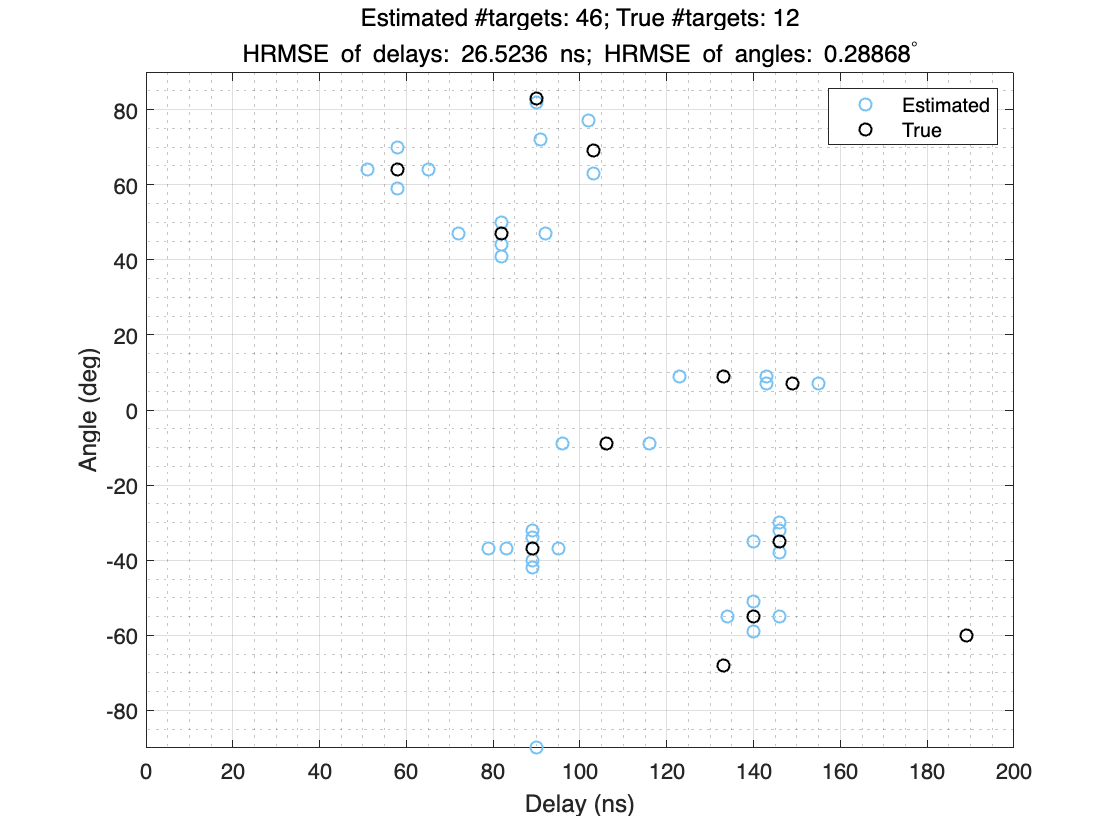

figure
plot(delays_est * 1e9,angles_est,'o','Color',colors(2,:),'LineWidth',1); hold on;
plot(delays * 1e9,angles,'ok','LineWidth',1); hold off;
xlabel('Delay (ns)'); xlim([0 200]);
ylabel('Angle (deg)'); ylim([-90 90]);
title(['Estimated #targets: ',num2str(npaths_est),'; True #targets: ',num2str(npaths)], ...
    ['HRMSE of delays: ',num2str(HRMSE_delays*1e9),' ns; HRMSE of angles: ',num2str(HRMSE_angles),'^\circ'])
legend('Estimated','True')
grid on; grid minor;

## **8. Least Squares Gain Estimation**

Not only can correctly estimating gains give insights on the noise variance estimate, allowing maximal ratio combining (MRC) of the Rx signal across subbands and adaptive epsilon updates across slots, but the gains are also used in sensing as a highly-related metric for the target radar cross section (RCS). Some papers has suggested the use of channel gains for material identification in the context of ISAC. 

Note that **our objective function is the L-2,1 norm of the channel rather than similarity (which is imposed as a constraint) in compressed sensing part.** This may mean that the gains estimated in the compressed sensing part is inaccurate. Or, it may take an unnecessarily long period of time for it to converge, because now **after we know where the targets are in delay/angle domains,** we can estimate the gains through the traditional least-squares approach which is simpler, faster, and accurate enough:

$\mathbf{y}_k = \mathbf{D}_k \hat{\mathbf{g}_k}$, where $\mathbf{D}_k$ is the **reduced** **full** **dictionary**, where each column is the **kronecker** product of the A1-column and A2-column corresponding to the estimated delay and angle index, respectively.

$\mathbf{D}_k = [\mathbf{a}_k^{\tt{1}} (\hat{\tau}_1) \otimes \mathbf{a}_k^{\tt{2}} (\hat{\theta}_1), \dots, \mathbf{a}_k^{\tt{1}} (\hat{\tau}_{\hat{N}}) \otimes \mathbf{a}_k^{\tt{2}} (\hat{\theta}_\hat{N})]$, where $\hat{N}$ is the estimated number of targets.

So $\hat{\mathbf{g}_k} = \mathbf{D}_k^{\dagger} \mathbf{y}_k $.

gains_est = zeros(npaths_est,K);

for k = 1:K
    % Construct reduced full dictionary D
    D = [];
    for nhat = 1:npaths_est
        a1 = A1{k}(:, locs_delay(nhat));
        a2 = A2{k}(:, locs_angle(nhat));
        D(:,nhat) = kron(a1,a2);
    end
    gains_est(:,k) = gains_est(:,k)+pinv(D)*Y{k}(:);
end

% Hungarian RMSE (Percentage from original)
gainswPLPT = sqrt(db2pow(PT))*sqrt(PL).*gains;
HRMSE_gains = zeros(K,1);
for k = 1:K
    CostMatrix_gains_k = abs(gainswPLPT(:,k) - gains_est(:,k).').^2;
    assgains_k = matchpairs(CostMatrix_gains_k,1e10);
    HRMSE_gains(k) = sqrt(mean(abs(gainswPLPT(assgains_k(:,1),k) - gains_est(assgains_k(:,2),k)).^2));
end
HRMSE_gains_pct = 100 * HRMSE_gains ./ vecnorm(gainswPLPT(assgains_k(:,1),:),2,1).';

## 9. Gain Estimation Visualization

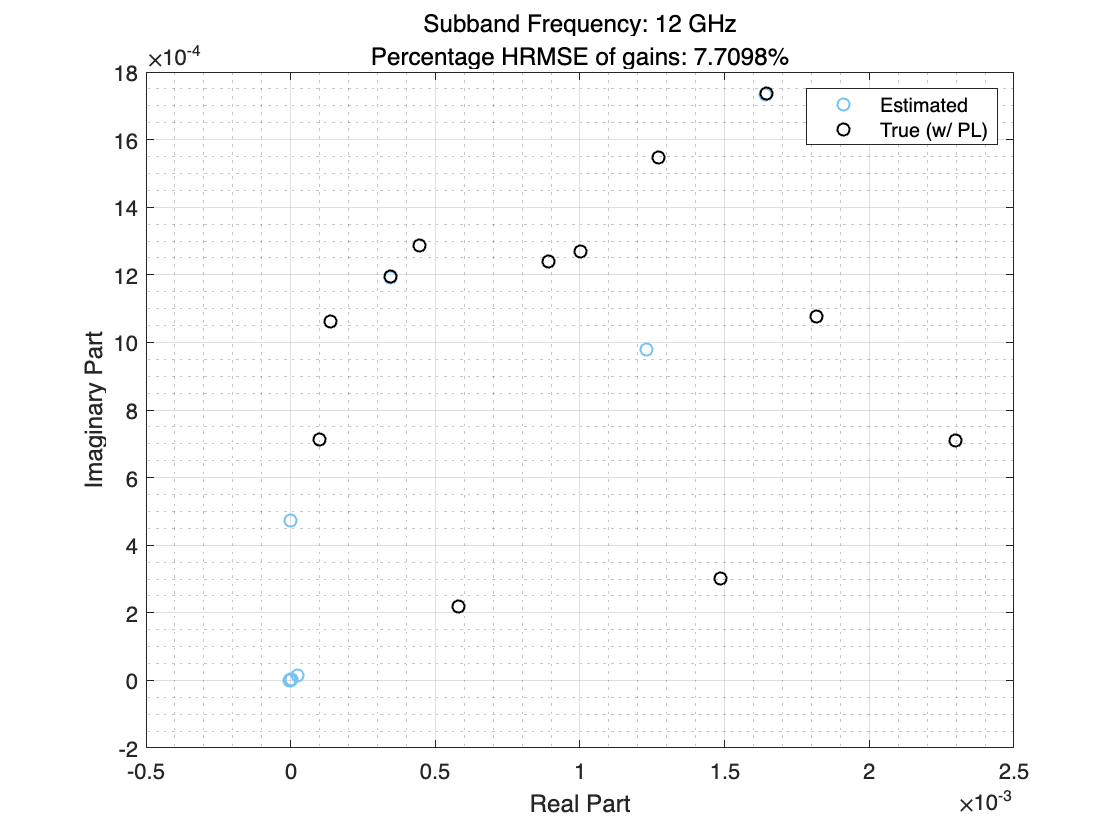

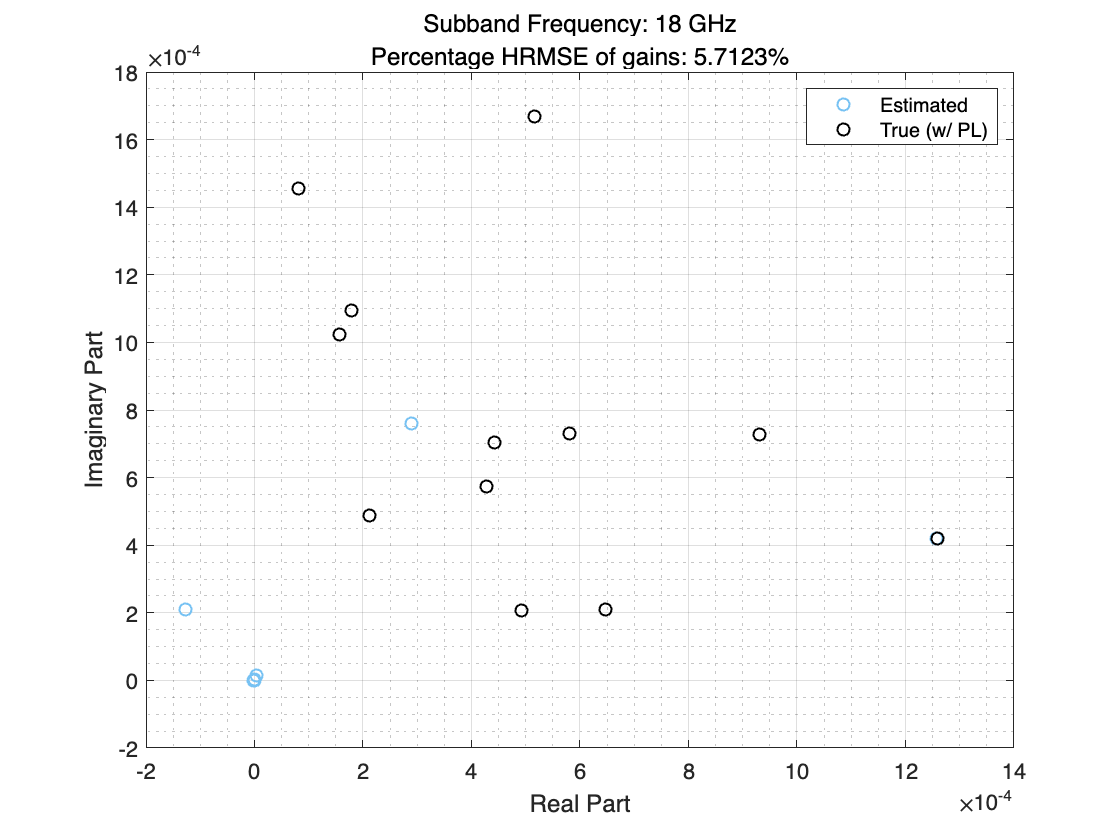

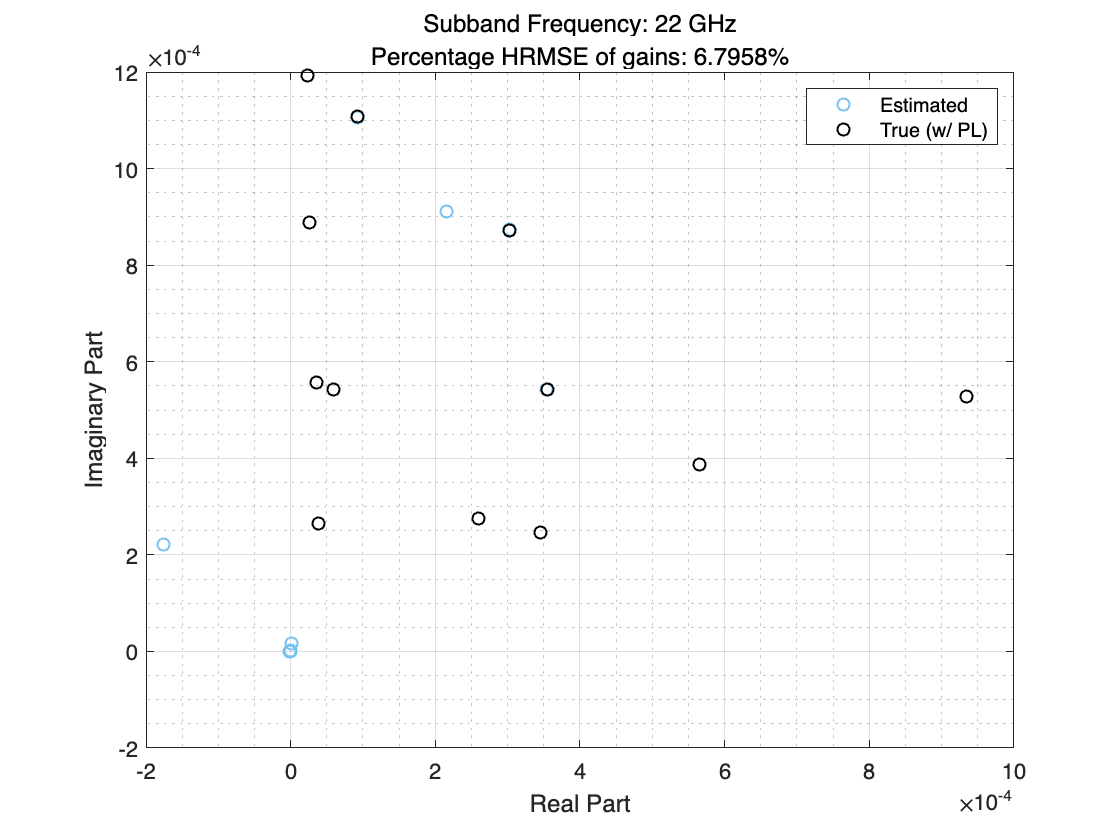

for k = 1:K
    figure
    axis equal;
    plot(real(gains_est(:,k)),imag(gains_est(:,k)),'o','Color',colors(2,:),'LineWidth',1); hold on;
    plot(real(gainswPLPT(:,k)),imag(gainswPLPT(:,k)),'ok','LineWidth',1); hold off;
    xlabel('Real Part');
    ylabel('Imaginary Part');
    legend('Estimated','True (w/ PL)')
    title(['Subband Frequency: ',num2str(MB_f(k)/1e9),' GHz'], ...
        ['Percentage HRMSE of gains: ',num2str(HRMSE_gains_pct(k)),'%']);
    grid on; grid minor;
end

## 10. Noise Variance and SNR Estimation

% Calculate and Display noise variance estiamte
for k = 1:K
    fb = MB_fb(k);
    d = MB_d(k);
    f = MB_f(k);

    % Reconstructed Channel Matrix (Hchan_recon)
    Hchan_recon = zeros(M,Q);
    for m = 1:M
        for q = 1:Q
            Hchan_recon(m,q) = sum(gains_est(:,k).*...
                exp(-1i*2*pi*(f+fb*(q-1))*delays_est) .*...
                exp(-1i*2*pi*d*f*(m-1)*sind(angles_est)/c)); % Narrowband approximation
        end
    end

    % Y - Hchan_recon .* s.'
    noisevar_est(k) = mean(abs(Y{k} - Hchan_recon.*s{k}.').^2,'all');
end
noisevar_total_est = sum(noisevar_est);
disp(['Total Noise variance estimate: ',num2str(noisevar_total_est)]);

Total Noise variance estimate: 1.2476e-08



% Calculate and Display SNR estimates
for k = 1:K
    snr_est(k) = pow2db(mean(abs(Y{k}).^2,'all') / noisevar_est(k));
    disp([num2str(MB_f(k)/1e9),' GHz', ...
        ' - SNR estimate: ',num2str(snr(k)),' dB']);
end

12 GHz - SNR estimate: 41.3895 dB
18 GHz - SNR estimate: 35.8477 dB
22 GHz - SNR estimate: 32.2448 dB
